# Calcoli di WCU, incertezza standard, incertezza estesa (con assegnata probabilità di copertura)

## Calcoli nota una popolazione di errori

% Dati
% Nsim = 1e6 = numero di campioni di errore nella popolazione
% e = valori di errore (matrice 1xNsim)
% cp1 = 0.9 = fattore di copertura n. 1
% cp2 = 0.95 = fattore di copertura n. 2
% cp3 = 0.9973 = fattore di copertura n. 3

% Domande
% fare un istogramma dell'errore
% b = bias della misura

% U = WCU
% u = incertezza standard

% br = bias ratio (rapporto tra bias e incertezza standard)

% Ucp1 % incertezza estesa con fattore di copertura cp1
% Ucp2 % incertezza estesa con fattore di copertura cp2
% Ucp3 % incertezza estesa con fattore di copertura cp3
% fare un istogramma dell'errore con le incertezze calcolate


% Codice iniziale
clear
Nsim = 1e6;
Ua = 0.5

Ua = 0.5000

Ub = 1

Ub = 1

Uc = 1.5

Uc = 1.5000

ea = unifrnd(-Ua,Ua,[1,Nsim]);
eb = unifrnd(-Ub,Ub,[1,Nsim]);
ec = unifrnd(-Uc,Uc,[1,Nsim]);
e = ea + eb + ec;
cp1 = 0.9

cp1 = 0.9000

cp2 = 0.95

cp2 = 0.9500

cp3 = 0.9973

cp3 = 0.9973

## Soluzione

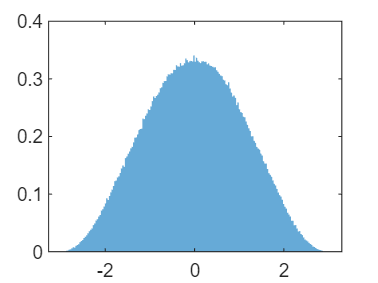

%con alt invio creo lo script

%faccio un istogramma dell'errore
histogram(e, "Normalization", "pdf", "EdgeColor","none")

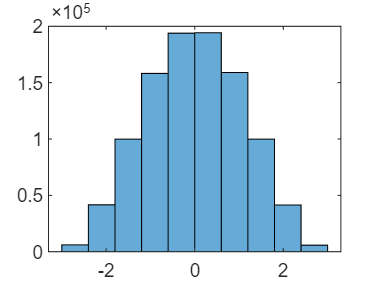

histogram(e, "Normalization", "count", "EdgeColor","k", "NumBins", 10) %esempio


%b = bias della misura
% b = E[e]
b = sum(e)/Nsim

b = -3.0844e-04

b = mean(e)

b = -3.0844e-04


%U = WCU
%u = incertezza standard
U = max(abs(e))

U = 2.9901

% u = E[(e-b)^2]
u = sqrt(mean((e-b).^2))

u = 1.0788

u = sqrt(mean(e.^2)) %se considero b=0

u = 1.0788

u = std(e) %normalizza per Nsim - 1

u = 1.0788

u = sqrt(sum(e.^2)/Nsim)

u = 1.0788


%br = bias ratio (rapporto tra bias ed incertezza standard)
br = b/u

br = -2.8592e-04


%Ucp1 incertezza estesa con fattore di copertura cp1
Ucp1 = quantile(e,(1+cp1)/2)

Ucp1 = 1.7766

%Ucp2 incertezza estesa con fattore di copertura cp2
Ucp2 = quantile(e,(1+cp2)/2)

Ucp2 = 2.0275

%Ucp3 incertezza estesa con fattore di copertura cp3
Ucp3 = quantile(e,(1+cp3)/2)

Ucp3 = 2.6266

## Calcoli note informazioni sull'errore, usando l'approssimazione gaussiana

% Una misura è la somma di tre misure:
% theta = a + b + c
%
% L'errore di misura è di conseguenza la somma dei tre errori:
% e = ea + eb + ec 
%
% Gli errori sono tutti a distribuzione uniforme, e tra loro indipendenti.
%
% Nota:
% 1) Per un errore somma di errori indipendenti:
% la varianza è la somma delle varianze
%
% 2) Per un errore somma di almeno tre errori indipendenti di varianze confrontabili:
% la pdf è approssimativamente gaussiana (teorema del limite centrale)

% Dati
% Ua = WCU misura a
% Ub = WCU misura b
% Uc = WCU misura c

% cp1 = 0.9 = probabilità di copertura n. 1
% cp2 = 0.95 = probabilità di copertura n. 2
% cp3 = 0.9973 = probabilità di copertura n. 3

% Domande
% U_theta = incertezza di caso peggiore della misura theta =
% max(abs(e_theta) con e_theta = ea + eb + ec

% ua = incertezza standard misura a
% ub = incertezza standard misura b
% uc = incertezza standard misura c

% u_theta = incertezza standard della misura theta = std(e_theta)

% k1 = fattore di copertura per cp1
% k2 = fattore di copertura per cp2
% k3 = fattore di copertura per cp3

% Ucp1_theta = incertezza estesa della misura theta con probabilità di copertura cp1
% Ucp2_theta = incertezza estesa della misura theta con probabilità di copertura cp2
% Ucp3_theta = incertezza estesa della misura theta con probabilità di copertura cp3

% Per quali incertezze estese l'approssimazione gaussiana non è valida?

% Codice iniziale
% nessuno

## Soluzione

U_theta = Ua + Ub + Uc %perchè gli errori sono indipendenti

U_theta = 3

%max(abs(e))
ua = Ua/sqrt(3)

ua = 0.2887

ub = Ub/sqrt(3)

ub = 0.5774

uc = Uc/sqrt(3)

uc = 0.8660


u_theta = sqrt(ua^2 + ub^2 + uc^2)

u_theta = 1.0801

std(e)

ans = 1.0804


k1 = norminv((1+cp1)/2)

k1 = 1.6449

k2 = norminv((1+cp2)/2)

k2 = 1.9600

k3 = norminv((1+cp3)/2)

k3 = 3.0000


Ucp1_theta = u_theta*k1 

Ucp1_theta = 1.7766

Ucp2_theta = u_theta*k2

Ucp2_theta = 2.1170

Ucp3_theta = u_theta*k3 %non funziona bene con l'approssimaione gaussiana

Ucp3_theta = 3.2403

%Se il risultato è più piccolo significativamente della WCU, allora
%l'approssimazione sta funzionando. (In caso contrario, no).
%Se il risultato è maggiore della WCU esso è chiaramente assurdo e
%l'approssimazione gaussiana non sta funzionando

Addendum: calcolare il massimo valore attribuibile al fattore di copertura senza rendere l'incertezza estesa maggiore di quella di caso peggiore

k_max = U_theta/u_theta

k_max = 2.7775

## Confronto tra calcoli con la popolazione $e$ e con l'approssimazione gaussiana

% Tracciare la pdf gaussiana dell'errore con incertezza standard u_theta, 
% Tracciare il grafico per ascisse tra -1.5*U e 1.5*U
% Tracciare linee verticali corrispondenti alle incertezze standard ed estese
% Sovrapporre l'istogramma della popolazione di errori e, e le incertezze calcolate dalla
% popolazione

## Soluzione

U = max(abs(e))

U = 2.9824

u = std(e)

u = 1.0804

Ucp1 = quantile(e,(1+cp1)/2)

Ucp1 = 1.7834

Ucp2 = quantile(e,(1+cp2)/2)

Ucp2 = 2.0346

Ucp3 = quantile(e,(1+cp3)/2)

Ucp3 = 2.6335



x = linspace(-1.5*U,1.5*U,1000)

x =    -4.4736   -4.4647   -4.4557   -4.4467   -4.4378   -4.4288   -4.4199   -4.4109   -4.4020   -4.3930   -4.3840   -4.3751   -4.3661   -4.3572   -4.3482   -4.3393   -4.3303   -4.3214   -4.3124   -4.3034   -4.2945   -4.2855   -4.2766   -4.2676   -4.2587   -4.2497   -4.2407   -4.2318   -4.2228   -4.2139   -4.2049   -4.1960   -4.1870   -4.1781   -4.1691   -4.1601   -4.1512   -4.1422   -4.1333   -4.1243   -4.1154   -4.1064   -4.0974   -4.0885   -4.0795   -4.0706   -4.0616   -4.0527   -4.0437   -4.0348


f = normpdf(x,0,u_theta)

f =     0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003


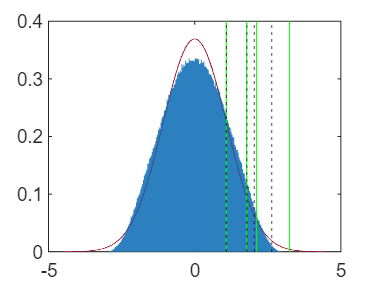

plot(x,f)
xline([u_theta,Ucp1_theta,Ucp2_theta,Ucp3_theta],"g")
hold on
histogram(e, "Normalization","pdf", "EdgeColor","none")
xline([u,Ucp1,Ucp2,Ucp3],":k")
hold off